Carichiamo un test per le impronte e uno per le frenate dry

% Impronte dinamiche
Impronte=load('Z:\TestData\SampleB\OutdoorTest\Audi_A4\19WK12_AudiA4_ObjHandlingLoop\20190322_DynamicFootprint\acquisition\set5\test\set5_v100_22-03-2019_14-06-24.test.mat');

% Vcost prima delle frenate dry
Frenate=load('Z:\TestData\SampleB\OutdoorTest\Audi_A4\19WK12_AudiA4_ObjHandlingLoop\20190329_DryBraking\acquisition\set7\test\set7_50cost_29-03-2019_11-25-39.test.mat');

 Partiamo da due dati affini che abbiamo:

        1) Segnale foniche 


$$w_{\mathrm{as},\mathrm{pd}} =\frac{\mathrm{N°}\;\mathrm{denti}}{\mathrm{tempo}}\;\left\lbrack \mathrm{Hz}\right\rbrack$$


**ACHTUNG**:si chiama w, ma in realtà è una frequenza

        2) velocità ruote da CAN veicolo


$${\mathrm{Radgeschw}}_{\mathrm{VR},\mathrm{HR}} =w_{\mathrm{wheel}} *R_{\mathrm{unknown}} \;\left\lbrack \frac{\mathrm{km}}{h}\right\rbrack$$
 


$${\textrm{Radgeschw}}_{\textrm{VR},\textrm{HR}} =\frac{w_{\textrm{wheel}} *R_{\textrm{unknown}} }{3\ldotp 6}\;\left\lbrack \frac{m}{s}\right\rbrack$$
 

Per trasformare il segnale foniche in velocità di rotazione della ruota abbiamo bisogno del numero di denti presenti nella foniche.

Se $1\;\mathrm{giro}\;\mathrm{ruota}=k\;\mathrm{denti}$ 

allora $\frac{w_{\mathrm{as},\mathrm{pd}} }{k}=n\;\left\lbrack \frac{\mathrm{giri}}{s}\right\rbrack$ 

e dunque $w_{\mathrm{wheel}} \;=n\;*2\pi =\frac{w_{\mathrm{as},\mathrm{pd}} }{k}*2\pi$

Sostituendo nell'equazione precedente e esplicitando *k* abbiamo:


$$k=\;$$

$$\frac{w_{\textrm{as},\textrm{pd}} }{{\mathrm{Radgeschw}}_{\mathrm{VR},\mathrm{HR}} }*3\ldotp 6*2\pi *R_{\textrm{unknown}}$$


Eseguendo questo calcolo su tutti  i punti acquisiti e ipotizzando un valore ragionevole di $R_{\textrm{unknown}}$ = 0.328 m si ha

Impronte.k_mean=mean(Impronte.DecodedCAN.Data1_w_ad*2*pi*0.32./Impronte.DecodedCAN.Data1_ESP_VR_Radgeschw*3.6);
Frenate.k_mean=mean(Frenate.DecodedCAN.Data1_w_ad*2*pi*0.32./Frenate.DecodedCAN.Data1_ESP_VR_Radgeschw*3.6);

disp(Impronte.k_mean)

  998.5832



disp(Frenate.k_mean)

  999.0939



Plottato si ottiene (smoothando le foniche che sono molto rumorose): 

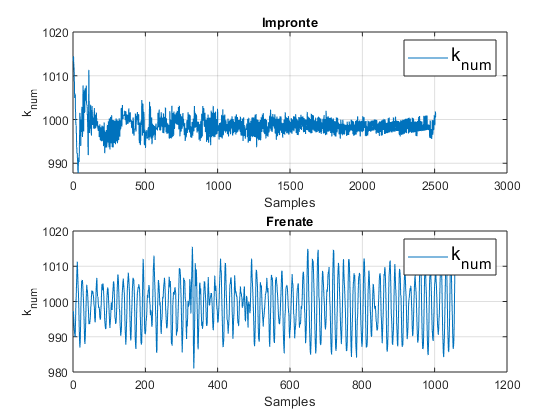

subplot(2,1,1)
plot(smoothdata(Impronte.DecodedCAN.Data1_w_ad)*2*pi*0.32./Impronte.DecodedCAN.Data1_ESP_VR_Radgeschw*3.6,'DisplayName','k_n_u_m')
grid on
legend('show','FontSize',14)
xlabel('Samples')
ylabel('k_n_u_m')
title('Impronte')

subplot(2,1,2)
plot(smoothdata(Frenate.DecodedCAN.Data1_w_ad)*2*pi*0.32./Frenate.DecodedCAN.Data1_ESP_VR_Radgeschw*3.6,'DisplayName','k_n_u_m')
grid on
legend('show','FontSize',14)
xlabel('Samples')
ylabel('k_n_u_m')
title('Frenate')

L'ho fatto solo per l'anteriore destra, se non ti fidi fallo per le altre ma, una volta trovato per una, basta vedere se in rettilineo sono tutte simili.

Ciao ciao

A.L.